# **High-Speed Wireline Link Optimization Demo**

Author: Junbo Wang, Ali Sheikholeslami

Affiliation: University of Toronto, ECE Department

Date: September 2025

Project: ECE2500 – High-Speed Wireline Link Optimization

## **Background**

This live script (`RunDemo.mlx`) provides a demontration of the link optimization algorithm presented in the paper **"High-Speed Wireline Links—Part II: Optimization and Performance Assessment" **by Shakiba, Tonietto, and Sheikholeslami, IEEE OJSSCS, 2024. Rather than performing a full multi-parameter sweep, this script is designed to **execute a single iteration** of the optimization flow based on **one specific user-defined set of swept parameters**. Its purpose is to:

- Illustrate the mechanics of equalization blocks;

- Demonstrate the process of computing optimal TX/RX FFE and DFE tap coefficients;

- Serve as an educational resource for understanding equalization and performance trade-offs in high-speed wireline links.

### Script Behavior 

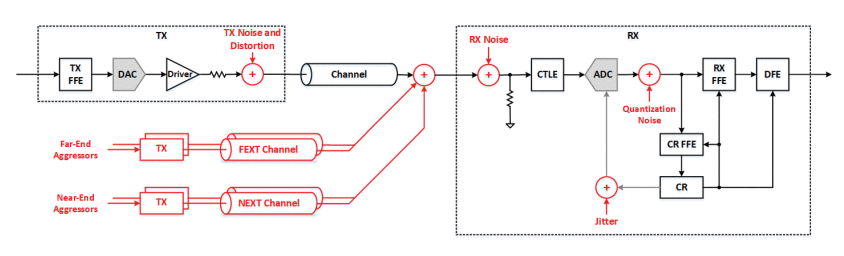

- **Execution Flow**: The simulation proceeds in the natural signal path order, starting from the transmitter, through the channel, and into the receiver. Equalization is applied step by step using the configured TX FFE, CTLE, VGA, RX FFE, and DFE blocks

- **User Settings**: All simulation and design parameters--including fixed values and swept parameter range and resolution--should be defined in the external script, `ConfigureUserSettings.m `(User must review this file and make the desirable edits before proceeding)

                *-- Select the pre-defined channel, simply uncomment the channel of your choice and comment out the original channel*

*                -- This file enables the use of ****Parallel Computing Toolbox**** which must be installed on MATLAB*

- **Optimization**: For the selected parameter set, the script computes optimal TX FFE coefficients to suppress pre-cursor ISI and optimal RX FFE and DFE coefficients to enhance the main cursor and remove residual ISI. It also visualizes the resulting pulse reponses, EQ frequency responses, and their effect at each stage

- **Output**: The script displays pulse responses at the input and output of key equalization blocks, frequency responses of the CTLE and VGA, and annotated plots to clarify the role and impact of each EQ block

***Note****: This script does ****NOT**** perform global optimization. To explore the entire parameter space and find the best configuration, a full multi-dimensional sweep is implemented in *`RunFullParallel.m`* as outlined in Algorithm 1 of the reference paper.*

### Final Remarks

This script is best used as a learning and experimentation tool. You are encouraged to: 

- Modify parameters sets in GenerateUserSettings.m

- Observe how equalizer design changes pulse responses

- Find the optimal set of parameters by running the full optimization script

All methods and mathematical formulations in this script are derived from **"High-Speed Wireline Links—Part II: Optimization and Performance Assessment" **H. Shakiba, D. Tonietto, A. Sheikholeslami, *IEEE Open Journal of Solid-State Circuits Systems*, July 2024.

DOI: 10.1109/OJSSCS.2024.3421868

  
clearvars;    % Reset workspace
close all;

## **Step 0: Configure Simulation Settings and Channel Models**

The first step in the simulation is to call `ConfigureUserSettings()`, which initializes all required link settings and prepares channel models for analysis.

This function performs the following key tasks:

- **Defines simulation parameters** such as data rate, PAM level, sampling resolution, and target equalizer structures (TX FFE, RX FFE, DFE).

- **Specifies fixed and swept parameters**, including termination resistances, CTLE pole-zero locations and gains, VGA gain, and receiver bandwidth. In this demo, only a single point in the sweep space is used.

- **Loads the S-parameter data** for the main channel and crosstalk aggressors (NEXT/FEXT).

- **Fits rational functions** to the S-parameter data to create compact analytical models for each port (S11, S12, S21, S22). These rational models are used in place of raw S-parameter lookups.

### **Why Rational Fitting?**

Rational fitting is critical for extending the usability and accuracy of the S-parameter models:

- It allows **continuous interpolation and extrapolation** beyond the discrete frequency points defined in `.s4p` files, enabling simulation at arbitrary frequency resolutions.

- It supports **efficient time-domain convolution** via impulse response generation.

- It enables **reuse across simulations** by caching the fitted models, reducing runtime.

Once this step completes, all models and settings are stored in `simSettings` and `simResources`, ready to be used throughout the rest of the simulation.

 
[simSettings,simResources] = ConfigureUserSettings();

'gcp' requires Parallel Computing Toolbox.

Error in ConfigureUserSettings (line 128)
    if isempty(gcp('nocreate'))

## **Step 1: Generate Input Signal and Visualize Channel Frequency Response**

After defining the simulation parameters and channel models, the next stage prepares the **excitation signal** and visualizes the **frequency-domain behavior** of the channel and its crosstalk environment.

### **Signal Generation: **`GenerateInput`

We begin by generating a simple **unit pulse** (single ‘1’ surrounded by zeros) to serve as the time-domain input stimulus. This isolated symbol allows us to observe the full impulse response of the system—including the spread of inter-symbol interference (ISI)—as it propagates through the channel and equalization blocks.

The resulting time-domain signal is sampled at a high rate (e.g., 64 samples/symbol) for accurate interpolation and distortion tracking.

### Transmitter Driver Filter: `ApplyDriverFilter`

the transmitter driver is modeled as a **low-pass filter** that shapes the output waveform by limiting the rise and fall times of the transmitted signal.

Mathematically, the driver's impulse and frequency responses are:


$$h_{\mathrm{driver}} \left(t\right)=a\sqrt{\pi }e^{-{\left(\mathrm{at}\right)}^2 } ,H_{\mathrm{driver}} \left(f\right)=e^{-{\left(\pi f/a\right)}^2 }$$


where:


$$a=\frac{0\ldotp 8}{T_t },$$


and $T_t$ is the 20%-80% rise/fall transition time in seconds.

In our implementation, the filter is applied directly in the frequency domain by multiplying the input spectrum $Y\left(f\right)$ with $H_{\textrm{driver}} \left(f\right)$. The filtered signal is then converted back into the time domain for visualization using an inverse FFT.

### **Frequency Response Visualization: **`GenerateFreqResponse`

To complement the time-domain analysis, we plot the **magnitude frequency response** of:

- The **main channel** (THRU), and

- All defined **crosstalk aggressor channels** (NEXT/FEXT).

These plots are generated directly from the original `.s4p` S-parameter files and provide insight into:

- Overall channel attenuation vs. frequency,

- Spectral regions affected by crosstalk,

- Equalization requirements for high-frequency compensation.

Understanding the frequency response at this stage helps inform design decisions for CTLE/VGA gain shaping and tap placement in subsequent steps.

 
% Define Load and Source Impedance (Ohm)
simSettings.zl = 50;
simSettings.zs = 50;

% Generate input signal
simResult_1 = GenerateInput(simSettings, false);

% Apply Driver Filter
simResult_1 = ApplyDriverFilter(simResult_1, simSettings);

% Plot signal
[simResult_1.cursorTimes, simResult_1.cursorValues] = ExtractCursors(simResult_1, simSettings);
DisplayOutput(simResult_1,simSettings,'Input Pulse at Driver Filter Output');
% Display Frequency Response
DisplayFreqResponse(simSettings);

## **Step 2: Apply Channel and Visualize Pulse Response**

After generating the input signal, we now simulate how it propagates through the channel using the previously computed rational models.

### **Channel Filtering: **`ApplyChannel`

The function `ApplyChannel` evaluates the **frequency-domain behavior** of the channel using the rational models of the S-parameters ($S_{11}$, $S_{12}$, $S_{21}$, $S_{22}$) fitted in Step 1. The transfer function $H\left(f\right)$ from source to load is computed using the formula from the paper: 


$$H\left(f\right)=S_{21} \left(f\right)\frac{\left(1-\Gamma_1 \right)\left(1+\Gamma_2 \right)}{1-S_{11} \left(f\right)\Gamma_1 -S_{22} \left(f\right)\Gamma_2 +\Gamma_1 \Gamma_2 \Delta_S \left(f\right)}$$


where:

- $\Gamma_1 =\frac{2Z_S -Z_0 }{2Z_S +Z_0 }$ and $\Gamma_2 =\frac{2Z_L -Z_0 }{2Z_L +Z_0 }$ are the reflection coefficients at the transmitter and receiver

- $\Delta_S \left(f\right)=S_{11} \left(f\right)S_{22} \left(f\right)-S_{12} \left(f\right)S_{21} \left(f\right)$ is the determinant of the S-matrix

- $Z_S$, $Z_L$, $Z_0$ are the source, load and reference impedances, respectively

This models both forward transmission and reflection effects, making it more accurate than a basic S21-only approach.

The input signal is transformed to the frequency domain using an FFT:


$$X\left(f\right)=\mathcal{F}\left\lbrace x\left(t\right)\right\rbrace$$


and then filtered:


$$Y\left(f\right)=H\left(f\right)\cdot X\left(f\right)$$


Finally, the time-domain channel output is recovered via inverse FFT:


$$y\left(t\right)={\mathcal{F}}^{-1} \left\lbrace Y\left(f\right)\right\rbrace$$


### **Cursor/Tap Extraction: **`ExtractCursors`

To characterize the channel in symbol-spaced terms, we extract the ISI taps $h_k$ centered around the main cursor $h_0$:

- We locate the maximum sample in the output signal which is assumed to be the main cursor $h_0$ at $t_0$

- Then sample values spaced by the symbol period $T_{\textrm{sym}}$ before and after to get pre- and post-cursors:


$$h_k =y\left(t=t_0 +k\cdot T_{\textrm{sym}} \right),\;\;k=-N_{\textrm{pre}} ,\ldots,\;0,\ldots,N_{\textrm{post}}$$


This results in a discrete channel impulse response:


$$\mathbb{h}=\left\lbrack h_{-N_{\textrm{pre}} } ,\ldots,h_{-1} ,h_0 ,h_1 ,\ldots,h_{N_{\textrm{post}} } \right\rbrack$$


which captures how much interference each adjacent symbol contributes to the sampling point.

### **Visualization: **`DisplayOutput`

The extracted taps are then visualized using a stylized pulse response plot:

- Time is normalized to **UI (unit interval)**,

- Signal is scaled to **millivolts**,

- Taps are labeled using standard notation: $h_0 ,h_{-1} ,h_1$, etc.

This matches the presentation in the paper (e.g., Fig.3, Fig.4), providing visual clarity into:

- How well the channel concentrates energy in the main cursor

- How much pre- and post-cursor ISI must be equalized

- Where to place equalizer taps and which blocks should handle which distortions

 
% Apply channel
simResult_2 = ApplyChannel(simResult_1, simSettings, simResources);

% Plot response
[simResult_2.cursorTimes, simResult_2.cursorValues] = ExtractCursors(simResult_2, simSettings);
DisplayOutput(simResult_2,simSettings,'Pulse Response at Channel Output (w/o TX FFE)');

## Step 3: Apply RX Front-End Equalization (Bandwidth Limitation, CTLE, and VGA)

In this step, we simulate the **analog front-end of the receiver**, which includes three key blocks:

- **RX Bandwidth Limitation** (representing input filtering due to parasitics and front-end bandwidth)

- **Continuous-Time Linear Equalizer (CTLE)**

- **Variable Gain Amplifier (VGA)**

These blocks shape the signal before it is passed to the digital equalizers (FFE/DFE) later in the chain.

### Package Interface Modeling

The TX and RX packages introduce a **series inductance** and **shunt capacitances** that low-pass the signal and can add peaking/ringing if not ordered carefully with other analog blocks. A compact and effective model is a single-section LC π-ladder per side:

- $L_s$: series inductance (bondwire/ball/pin)

- $C_b$: bump-side (board/package) capacitance (TX side)

- $C_d$: die-side capacitance (RX side)

The LC π-ladder naturally introduces a high-frequency zero, causing the magnitude response to rise again at very high frequencies. Left unchecked, this peaking excites oscillatory components when transformed back to the time domain, producing ringing artifacts in the impulse response.

To suppress this, the RX bandwidth filter is placed *immediately after* the package stage. Its roll-off damps the package's HF zero, ensuring a smooth response and stable time-domain waveform.

### **3a. RX Bandwidth Limitation: **`ApplyReceiverBW`

The receiver front-end is set to a finite bandwidth, typically close to the **Nyquist frequency**:


$$f_{\textrm{Nyquist}} =\frac{f_{\textrm{data}} }{2}$$


This is modeled using a **4th-order Butterworth low-pass filter**, which has a flat passband and smooth roll-off:


$$H_{\textrm{RX}} \left(f\right)=\frac{1}{1-3\ldotp 4142{\left(\frac{f}{f_r }\right)}^2 +{\left(\frac{f}{f_r }\right)}^4 +\textrm{j2}\ldotp 6131\left(\frac{f}{f_r }-{\left(\frac{f}{f_r }\right)}^3 \right)}$$


The filter is implemented digitally using the `butter` function in MATLAB. This models real receiver limitations due to package parasitics, ESD clamps, or input amplifier stages.

*Note: After this step, we re-extract the pulse response to observe how much high-frequency energy is filtered.*

 
% Apply package
simResult_3a = ApplyPackage(simResult_2, simSettings);
% simResult_3a = simResult_2;

% Plot response
% [simResult_3a.cursorTimes, simResult_3a.cursorValues] = ExtractCursors(simResult_3a, simSettings);
% DisplayOutput(simResult_3a,simSettings,'Pulse Response after Applying Package Effect');

% Apply RX bandwidth limitation 
simResult_3a.rxBW = simSettings.dataRate * 0.55;
simResult_3a = ApplyReceiverBW(simResult_3a);

% Plot output
[simResult_3a.cursorTimes, simResult_3a.cursorValues] = ExtractCursors(simResult_3a, simSettings);
DisplayOutput(simResult_3a, simSettings, 'Pulse Response at CTLE Input after RX Bandwidth Limitation');
% Plot Comparison
% DisplayOutputComparison(simResult_3a, simSettings, 'Pulse Response at CTLE Input with and without RX Bandwidth Limitation','w/o RX BW Limitation','w/ RX BW Limitation');

### 3b. Continuous-Time Linear Equalizer (CTLE): `ApplyCTLE`

To compensate for high-frequency loss in the channel and RX front-end, a **CTLE** is applied. It acts like a band-pass filter that boosts high-frequency content while attenuating low frequencies.

The CTLE transfer function is defined in the frequency domain as:


$$H_{\textrm{CTLE}} \left(j\omega \right)={10}^{\frac{g_1 +g_2 }{20}} \cdot \frac{\left(1+j\omega /\omega_{\textrm{z1}} \right)\left(1+j\omega /\omega_{\textrm{z2}} \right)}{\left(1+j\omega /\omega_{\textrm{p1}} \right)\left(1+j\omega /\omega_{\textrm{p2}} \right)\left(1+j\omega /\omega_{\textrm{p3}} \right)}$$


- The **poles** $\omega_{\textrm{p1}}$, $\omega_{\textrm{p1}}$, $\omega_{\textrm{p1}}$ set the roll-off behavior

- The **zeros** $\omega_{\textrm{p1}}$, $\omega_{\textrm{p1}}$, $\omega_{\textrm{p1}}$ are derived from the pole positions and DC gains $g_1$, $g_2$ via: 


$$f_{\textrm{z1}} =f_{\textrm{p1}} \cdot {10}^{g_1 /20} ,\;f_{\textrm{z2}} =f_{\textrm{p2}} \cdot {10}^{g_2 /20}$$


The signal is equalized in the frequency domain using: 


$$Y\left(f\right)=X\left(f\right)\cdot H_{\textrm{CTLE}} \left(f\right)$$


This stage is crucial for mitigating high-frequency ISI before the VGA and slicer.

*Note: The CTLE shape and gain directly impact the tradeoff between noise amplification and ISI cancellation.*

### **Visualization: **`DisplayOutput`** and **`DisplayOutputComparison`

After each block (bandwidth limitation, CTLE, VGA), the pulse response is re-extracted and:

- Plotted using the same stylized format as in earlier steps,

- Compared side-by-side with previous outputs using `DisplayOutputComparison`.

These plots help visually evaluate:

- How the **main cursor** $h_0$ and surrounding ISI taps are reshaped,

- How much high-frequency content is recovered,

- The combined effect of CTLE + VGA on amplitude and ISI spread.

 
simResult_3b = simResult_3a;
% Apply CTLE
simResult_3b.eq.ctle.g1 = -10;
simResult_3b.eq.ctle.g2 = -4;
simResult_3b.eq.ctle.fp1 = simSettings.dataRate / 2.5;
simResult_3b.eq.ctle.fp2 = simSettings.dataRate / 80;
simResult_3b.eq.ctle.fp3 = simSettings.dataRate;
% simResult_3b.eq.ctle.fp1 = 26000000000;
% simResult_3b.eq.ctle.fp2 = 500000000;
% simResult_3b.eq.ctle.fp3 = 54000000000;
simResult_3b = ApplyCTLE(simResult_3b);

% Plot output
[simResult_3b.cursorTimes, simResult_3b.cursorValues] = ExtractCursors(simResult_3b, simSettings);
% DisplayOutput(simResult_3b,simSettings,'Pulse Response at CTLE Output');

% Plot Comparison
DisplayOutputComparison(simResult_3b, simSettings, 'Pulse Response at VGA Input with and without CTLE','w/o CTLE','w/ CTLE');

 
% Plot CTLE Frequency Response
% DisplayCTLE(simResult_3b, simSettings);

### 3c. Variable Gain Amplifier (VGA): `ApplyVGA`

The VGA applies a user-defined **gain** and optional bandwidth limitation, modeled as a **first-order low-pass filter:**


$$H_{\textrm{VGA}} \left(s\right)=\frac{K}{1+{s/\omega }_c },\textrm{with}\;K={10}^{{\textrm{Gain}}_{\textrm{dB}} /20} ,\omega_c =2\pi f_{\textrm{BW}}$$


This stage:

- Amplifies the CTLE output to better match the slicer or ADC dynamic range,

- Optionally rolls off out-of-band noise.

It is implemented using `bilinear` to discretize the analog filter.

 
simResult_3c = simResult_3b;
% Apply VGA
% simResult.eq.vga.gain = 10;
simResult_3c.eq.vga.gain = 15;
simResult_3c.eq.vga.bw = 1e12;
simResult_3c = ApplyVGA(simResult_3c);

% Plot output
[simResult_3c.cursorTimes, simResult_3c.cursorValues] = ExtractCursors(simResult_3c,simSettings);
DisplayOutput(simResult_3c,simSettings,'Pulse Response at VGA Output');

## Step 4: TX FFE Optimization and Application

In this step, we design and apply the **transmitter Feedforward Equalizer (TX FFE)**, which pre-distorts the input signal to mitigate precursor ISI observed at the receiver after analog front-end filtering (i.e., after CTLE and VGA).

Although TX FFE operates at the **transmitter**, its tap weights are optimized based on the **pulse response measured at the CTLE output**, as this captures the true ISI environment the equalizer must address.

### Objective

The TX FFE is optimized to produce a pulse response at the receiver input with:

- Zero pre-cursors (i.e., $h_k =0$ for $k<0$)

- A single non-zero main cursor $h_0$

Post-cursor cancellation is intentionally **left to the RX-side equalizers** (CTLE, RX FFE, and DFE) to take advantage of their superior post-ISI cancellation ability.

### Mathematical Formulation (from Paper Sec. III.C.1)

Let:

- $h=\left\lbrack h_{-N+1} ,\ldots,h_0 \right\rbrack$ be a vector of the CTLE output impulse response (pre-cursors and main cursor)

- $H\in {\mathbb{R}}^{N\times \left(2N-1\right)}$ be the pulse response matrix constructed from shifts of $h$

- $g^* \in {\mathbb{R}}^{1\times \left(2N-1\right)}$ be the target pulse response, with all zeros except at the main cursor index:


$$g^* =\left\lbrack 0\;0\ldots0\;h_0 \right\rbrack$$


We want to find FFE tap weights $v\in {\mathbb{R}}^{1\times N}$ such that:


$$v=\arg \;\min_v \;||v\cdot H-g^* ||^2$$


This is a **minimum mean-square error (MMSE) projection**, and the solution is:


$$v_{\textrm{opt}} =g^* \cdot H^T \cdot {\left(H\cdot H^T \right)}^{-1}$$


Finally, we normalize the tap vector to preserve constant TX swing:


$$v_{\textrm{norm}} =\frac{v_{\textrm{opt}} }{\sum_k |v_{\textrm{opt}} \left(k\right)|}$$


This guarantees compliance with TX output swing constraints, regardless of tap ratios.

### MATLAB Implementation

- `AdaptTransmitterFFE` extracts the required taps from the post-VGA pulse response, constructs the matrix $H$, and solves for the optimal tap vector.

- `ApplyFFE` applies the resulting TX FFE taps via **oversampled convolution** with the input signal.

- The result is a **filtered signal**, ready to pass through the passive channel model.

Although TX FFE is applied *before* the channel, adapting it using the **post-CTLE response** ensures the transmitter compensates for ISI *as seen at the receiver*.

### **Visualization**

After TX FFE is applied:

- We extract and plot the new pulse response.

- You should observe a **reduction in precursor amplitudes** (e.g., $h_{-1}$, $h_{-2}$) while the main cursor $h_0$ is preserved.

 
simResult_4 = simResult_3c;
% Compute optimal TX FFE taps
simResult_4.eq.tapsTXFFE = AdaptTransmitterFFE(simResult_4,simSettings);

% Apply TX FFE
simResult_4 = ApplyFFE(simResult_4,simResult_4.eq.tapsTXFFE,simSettings);

% Plot output
[simResult_4.cursorTimes, simResult_4.cursorValues] = ExtractCursors(simResult_4,simSettings);
plotTitle = sprintf('Pulse Response at VGA Output with %d-Tap TX FFE', simSettings.opt.numTXFFE);
DisplayOutput(simResult_4, simSettings, plotTitle);

## Step 5: RX Equalizer Optimization — FFE and DFE

In this step, we co-optimize the **receiver Feedforward Equalizer (RX FFE)** and **Decision Feedback Equalizer (DFE)** to maximize the main cursor signal quality while suppressing residual ISI and noise.

Unlike TX FFE (which focuses on precursor cancellation), the RX FFE is responsible for **enhancing the main cursor** and **mitigating post-cursor ISI**, while the DFE eliminates strong immediate post-cursors via feedback.

### **Overview of the Joint Optimization Process**

The optimization follows the **signal model** and **minimum mean-squared error (MMSE)** criterion described in the paper (Section III.C.2–3):

Let the observed impulse response at the RX FFE input be $h$, and the total equalizer response be:


$$y=w^T x$$


where:

- $x$ is the vector of input samples to the FFE

- $w$ is the RX FFE tap vector to be optimized

- $y$ is the estimated main cursor value at a candidate sampling location

The total equalization goal is to match the output response $y$ to an ideal main tap with DFE post-cursor feedback included.

### **DFE Tap Estimation: **`ExtractAlpha`

The DFE cancels the strongest post-cursor ISI tap(s) via feedback. We extract the value of the first post-cursor $h_1$ and use it to define the DFE coefficient $\alpha$, such that:


$$y\left\lbrack k\right\rbrack =\hat{x} \left\lbrack k\right\rbrack -\alpha \cdot \textrm{sign}\left(\hat{x} \left\lbrack k-1\right\rbrack \right)$$


This simplifies the RX FFE design, allowing us to treat $\alpha$ as known and incorporate it into the target impulse response during RX FFE optimization.

### **RX FFE Optimization: **`AdaptReceiverFFE`

This function performs an **MMSE optimization** over:

- The RX FFE tap vector $w$

- The **optimal sampling location** (i.e., index of the main cursor)

The optimization minimizes the cost function (from Eq. (4) in the paper):


$$\textrm{MMSE}=||X^T w-g||^2 +\sigma_n^2 \;||w||^2$$


Where:

- $X$ is the convolution matrix built from the channel impulse response

- $g$ is the desired response (with the DFE tap $\alpha$ inserted at the post-cursor location)

- $\sigma_n^2$ is the **input-referred noise power** at the RX FFE input estimated via:


$$\sigma_n^2 =\int_0^{f_s } S_n \left(f\right)\cdot |H_{\textrm{RX}} \left(f\right)|^2 \;df$$


This noise is shaped by the **RX bandwidth**, **CTLE**, and **VGA** frequency responses and computed numerically in `ComputeRxNoisePower`. 

### **Algorithm Summary**

For each candidate sampling index:

- Construct a desired response $g$ with DFE tap(s)

- Solve the regularized normal equations:


$$w_{\textrm{opt}} ={\left({\textrm{XX}}^T +\sigma_n^2 \;I\right)}^{-1} \cdot X\cdot g$$


- Compute MMSE cost

- Select the sampling index tap vector $w_{\textrm{opt}}$ that minimizes the MMSE

The RX FFE output is then computed using this optimal $w$ via convolution.

### **Visualization**

After applying the RX FFE:

- We re-extract and plot the resulting pulse response

- The plot should show a **strong main cursor** and **reduced pre- and post-cursors**

- This corresponds to Fig. 5 and Fig. 7 in the paper, showing optimized tap shaping post-equalization

 
simResult_5 = simResult_4;

% Extract alpha
simResult_5.eq.tapsDFE = ExtractAlpha(simResult_5,simSettings);

% Compute optimal RX FFE taps with DFE Co-Optimization
[simResult_5.eq.tapsRXFFE,simResult_5.optSamplingPoint] = AdaptReceiverFFE(simResult_5,simSettings);

% Apply RX FFE
simResult_5 = ApplyFFE(simResult_5,simResult_5.eq.tapsRXFFE,simSettings);

% Plot output
[simResult_5.cursorTimes, simResult_5.cursorValues] = ExtractCursors(simResult_5,simSettings);
plotTitle = sprintf('Pulse Response at DFE Input with %d-Tap TX FFE and %d-Tap RX FFE', simSettings.opt.numTXFFE, simSettings.opt.numRXFFE);
DisplayOutput(simResult_5,simSettings,plotTitle);

## Step 6: Apply DFE (Decision Feedback Equalizer)

At this stage, we apply a **Decision Feedback Equalizer (DFE)** to cancel the dominant **post-cursor ISI** that remains after TX FFE, RX FFE, and analog equalization (CTLE/VGA).

The DFE acts as a **nonlinear equalizer** that:

- Uses past **decisions** to subtract ISI from the current symbol

- Operates in **discrete time** at the symbol rate

- Works best when residual ISI is concentrated in the first few post-cursors (e.g., $h_1$)

### **Background (from Paper Sec. III.C.4)**

After RX FFE optimization, the output $y\left\lbrack n\right\rbrack$ still contains residual ISI from earlier symbols. The strongest component is typically the **first post-cursor**, which we denote by tap $\alpha$, i.e., $h_1$. 

The DFE applies the following **symbol-rate correction**:


$$\hat{y} \left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack -\alpha \cdot \hat{x} \left\lbrack n-1\right\rbrack$$


where:

- $y\left\lbrack n\right\rbrack$ is the RX FFE output

- $\hat{x} \left\lbrack n-1\right\rbrack \in \left\lbrace -1,+1\right\rbrace$ is the previous detected symbol, based on thresholding

- $\hat{y} \left\lbrack n\right\rbrack$ is the corrected value

This logic generalizes to multiple taps (length $N_{\textrm{DFE}}$):


$$\hat{y} \left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack -\sum_{k=1}^{N_{\textrm{DFE}} } \alpha_k \cdot \hat{x} \left\lbrack n-k\right\rbrack$$


In our case, $\alpha$ are extracted from the post-cursor tap values using `ExtractAlpha`.

### **Implementation: **`ApplyDFE`

This function applies **symbol-spaced DFE** by:

- Thresholding the RX FFE output to detect binary symbols, using $h_0 \;/\;2$ as the slicer threshold

- Using past decisions to subtract ISI caused by $\alpha_k$

- Spreading correction over each symbol interval for continuous-time alignment with the oversampled waveform

While DFE is typically implemented at the slicer in hardware, this model applies the effect directly to the oversampled waveform, allowing visual inspection of the result.

### **Visualization**

After applying the DFE:

- The updated pulse response is plotted using `DisplayOutput`,

- You should observe a **sharp reduction in early post-cursor taps** (especially $h_1$),

- The output now closely resembles an ideal pulse: a dominant $h_0$ and minimal surrounding ISI.

This corresponds to **Figure 6 in the paper**, which shows how DFE cleans up remaining ISI, leaving the signal ready for reliable slicing.

 
simResult_6 = simResult_5;

% Set DFE decision threshold
simResult_6.eq.thresh = max(simResult_6.cursorValues)/2;

% Extract alpha again
simResult_6.eq.tapsDFE = ExtractAlpha(simResult_6,simSettings);

% Apply DFE
simResult_6 = ApplyDFE(simResult_6,simSettings);

% Plot output
[simResult_6.cursorTimes, simResult_6.cursorValues] = ExtractCursors(simResult_6,simSettings);
plotTitle = sprintf('Pulse Response at Slicer Input with %d-Tap DFE', simSettings.opt.numRXDFE);
DisplayOutput(simResult_6,simSettings,plotTitle);

## **Step 7: Evaluate SNR (Signal-to-Noise Ratio)**

At the end of each simulation iteration, we compute the **effective SNR** of the received signal to evaluate the quality of the current link configuration. This metric determines how well the chosen parameter set (e.g., CTLE settings, FFE/DFE taps, terminations, etc.) suppresses ISI and noise.

In a full optimization loop (not shown in this demo), the configuration that yields the** maximum SNR** is selected as the optimal solution (See **Section III.C.5 **of the paper).

### **SNR Definition**

The SNR is computed using the cursor values extracted after RX FFE and before DFE. These taps characterize the sampled pulse response $h$, where:

- $h_0$ is the main cursor (desired signal)

- $h_{k\not= 0}$ are the pre- and post-cursors (intersymbol interference)

- $\sigma_n^2$ is the total noise power

The SNR is then defined as:


$$\textrm{SNR}=10\cdot \log_{10} \left(\frac{h_0^2 }{\sum_{k\not= 0} h_k^2 +\sigma_{n,\textrm{TX}}^2 +\sigma_{n,\textrm{RX}}^2 }\right)$$


This formula captures the **true post-equalization SNR**, accounting for:

- Residual ISI energy not canceled by the equalizers,

- Noise from both transmitter and receiver paths.

### **Noise Modeling Details**

The total noise power is calculated by shaping flat-spectrum noise through the entire signal path using the power gain of each block. Both **TX noise **and **RX noise **are modeled as white processes with constant spectral density over the Nyquist band, then shaped by the cascade of equalization and channel transfer functions.

#### TX Noise

- Defined by the **TX SNDR** in dB, referenced at **112 Gsym/s**.

- Converted into a flat **one-sided PSD**, in units of V²/Hz

- Shaped by: TX FFE, channel $S_{21}$, RX bandwidth limitation, CTLE, and VGA, and RX FFE


$$\sigma_{n,\textrm{TX}}^2 =\int |H_{\textrm{TX}} \left(f\right)|^2 \cdot S_{\textrm{TX}} \left(f\right)\;df$$


where


$$H_{\textrm{TX}} \left(f\right)=H_{\textrm{FFE},\textrm{TX}} \left(f\right)\cdot H_{\textrm{CH}} \left(f\right)\cdot H_{\textrm{BW}} \left(f\right)\cdot H_{\textrm{CTLE}} \left(f\right)\cdot H_{\textrm{VGA}} \left(f\right)\cdot H_{\textrm{FFE},\textrm{RX}} \left(f\right)$$


#### RX Noise

- Defined by RX noise **power spectral density (PSD) **specified in V²/Hz

- Shaped by RX bandwidth limitation, CTLE, VGA, and RX FFE


$$\sigma_{n,\textrm{RX}}^2 =\int |H_{\textrm{RX}} \left(f\right)|^2 \cdot S_{\textrm{RX}} \left(f\right)\;df$$


with


$$H_{\textrm{RX}} \left(f\right)=H_{\textrm{BW}} \left(f\right)\cdot H_{\textrm{CTLE}} \left(f\right)\cdot H_{\textrm{VGA}} \left(f\right)\cdot H_{\textrm{FFE},\textrm{RX}} \left(f\right)$$


*Note: These integrals are evaluated numerically in the script using the composite frequency response over a dense FFT grid (e.g., *$N=2^{16}$*).*

#### FFE Transfer Functions

The FFE blocks (TX FFE and RX FFE) are **discrete-time FIR filters** operating at the symbol clock (symbols/s). Given tap coefficients $h\left\lbrack k\right\rbrack$ for $k=0,1,\ldots,N-1$, the discrete-time frequency response is


$$H_{\textrm{FFE}} \left(e^{j\omega } \right)=\sum_{k=0}^{N-1} h\left\lbrack k\right\rbrack e^{-j\omega k} ,\omega \in \left\lbrack -\pi ,\pi \right\rbrack$$


To embed this in the analog-frequency domain, we map Hz to normalized frequency:


$$\omega =\frac{2\pi f}{R_s },f\in \left\lbrack 0,\frac{R_s }{2}\right\rbrack$$


Thus the effective continuous-frequency response of an FFE is


$$H_{\textrm{FFE}} \left(f\right)=\sum_{k=0}^{N-1} h\left\lbrack k\right\rbrack e^{-\textrm{j2}\pi f/R_s }$$


- **TX FFE:** precedes the channel and therefore shapes the TX noise spectrum before it propagates.

- **RX FFE:** follows the analog front-end and therefore shapes both TX noise and RX noise after they have been filtered by the analog path.

### Interpretation

- A **higher SNR** indicates a better-quality signal at the slicer input.

- As shown in **Fig. 7 and Fig. 8 of the paper**, SNR is a robust optimization metric because it balances ISI suppression with noise amplification.

- This final SNR value is used as the **figure of merit** when sweeping parameter sets across the design space.

 
simResult_6.SNR = EvalSNR(simResult_6, simSettings);
fprintf('SNR = %.4f dB\n', simResult_6.SNR);

## Performance Assessment: 2D PDF

After equalization and SNR evaluation, the final step of the simulation assesses the **statistical quality** of the signal at the **slicer input**, which ultimately determines bit error rate (BER).

Rather than computing BER directly (which is computationally expensive at low error rates), we estimate the **2D probability density function (PDF)** of the received signal across **time and amplitude**. This statistical representation captures the effects of:

- ISI (inter-symbol interference),

- TX/RX noise,

- Crosstalk,

- Sampling jitter.

The result is a **voltage-time density map** that can be used to:

- Visualize the **eye opening**,

- Estimate **symbol error rate** or **BER** via integration over the decision boundaries,

- Analyze **noise-limited** vs. **ISI-limited** behavior,

- Generate eye contours similar to those shown in **Fig. 9 and Fig. 10** of the paper.

### Why a 2D PDF? 

In a high-speed PAM system, the signal at the sampler is not deterministic—it varies due to:

- Timing uncertainty (jitter)

- Amplitude uncertainty (noise + ISI + crosstalk)

Thus, at each symbol time, the signal is better modeled as a **probability distribution** over voltage.

By stacking these distributions across a symbol period (or a unit interval), we build a **2D PDF**:


$$p\left(v,t\right)\;\;\;\left(\textrm{probability}\;\textrm{of}\;\textrm{amplitude}\;v\;\textrm{at}\;\textrm{time}\;t\right)$$


This continuous statistical model provides a complete view of how distortions affect the eye diagram over time.

### How Is the 2D PDF Constructed? 

The call to `GeneratePDF2D` triggers the construction of this 2D PDF by summing the effects of multiple contributors:

- `pdfISI`: The deterministic voltage distribution from ISI across symbols

- `pdfCrosstalk`: Modeled statistically using aggressor impulse responses and random transitions

- `pdfNoiseTX`, `pdfNoiseRX`: Gaussian distributions shaped by TX and RX frequency response

- `pdfJitter`: Temporal smearing modeled as a jitter PDF (usually Gaussian or Dirac-like)

- `pdfMainCursor`: Ideal response from a clean pulse

- `pdfTotal`: The convolution of all the above, producing the final total PDF

Each component is modeled independently, then combined using convolutions in the amplitude domain and smearing in the time domain to yield a realistic statistical model. 

The figure generated by `GeneratePDF2D` shows seven subplots, each representing one contributing component to the **probability density of the signal at the slicer input**. Together, they form a modular noise-and-distortion model that reflects how the signal degrades during transmission. 

### ISI PDF Generation: GeneratePdfISI

The **ISI (Inter-Symbol Interference) PDF** models the statistical distribution of the slicer input voltage due to residual ISI from previous and future symbols.

Even after equalization (TX FFE, RX FFE, and DFE), some energy from neighboring symbols remains in the signal. This leads to symbol-dependent voltage fluctuations at the sampling instant, which cause deterministic amplitude uncertainty.

Here is how it is computed: We assume that ISI arises from a superposition of random data symbols, each scaled by its associated pulse response tap. The uncertainty is therefore modeled as a zero-mean Gaussian distribution whose standard deviation depends on the energy of the ISI taps.

Let:

- $h_k$ be the cursor values (taps)

- $h_0$ is the main cursor (desired signal)

- $h_{k\not= 0}$ are the pre- and post-cursor ISI taps

- $M$ is the PAM level (e.g. 4 for PAM-4)

Then the ISI variance is estimated as:


$$\sigma_{\textrm{ISI}}^2 =\frac{1}{3}\cdot \frac{M+1}{M-1}\cdot \sum_{k\not= 0} h_k^2$$


This scaling factor $\frac{1}{3}\cdot \frac{M+1}{M-1}$ accounts for the variance of uniformly distributed PAM levels with spacing 2, assuming equiprobable symbols. We then generate a 1D Gaussian PDF with a standard deviation $\sigma_{\textrm{ISI}}$:


$$p_{\textrm{ISI}} \left(v\right)=\frac{1}{\sqrt{2\pi \sigma_{\textrm{ISI}}^2 }}\exp \left(-\frac{v^2 }{2\sigma_{\textrm{ISI}}^2 }\right)$$


This PDF is then reused at every time slice of the eye diagram to represent the ISI-induced vertical spread at each symbol level. In summary, this model assumes that ISI from neighboring symbols is uncorrelated and all symbol combinations are equally likely. 

*MATLAB Notes:*

- *The *`cursorValues`* vector includes all tracked taps; we exclude the main cursor when summing ISI power.*

- *The standard deviation *$\sigma$ *is computed in voltage units.*

- *The PDF is evaluated across the range *`simSettings.pdfRange`* with resolution *`pdfdx`*.*

### **Crosstalk PDF Generation: **`GeneratePdfCrosstalk`

In high-speed interconnects, crosstalk arises when signals from neighboring lanes (aggressors) couple into the victim line. Even with differential signaling and physical isolation, this coupled interference can cause voltage fluctuations at the slicer input, degrading eye opening and increasing error probability.

This function computes the voltage probability density due to crosstalk, and incorporates it into the total eye PDF. Each crosstalk aggressor is treated as an independent random PAM signal (uncorrelated with the victim data). Its time-domain effect on the victim is:

- Computed via the S-parameter transfer function of the aggressor channel (e.g., NEXT or FEXT)

- Propagated through the victim receiver's signal chain (CTLE, VGA, RX FFE) 

- Interpreted statistically as Gaussian-distributed noise, due to the randomness of aggressor transitions

The result is a zero-mean Gaussian distribution whose variance depends on:

- The aggressor channel's transfer function $H\left(f\right)$

- The equalization and filtering applied on the victim path 

- The aggressor signal's energy at each sampling phase.

#### Modelling Steps

For each aggressor channel:

**1. Apply Equalization Chain**

We start by processing the victim's own transmit waveform (after TX FFE) through the full receiver signal chain:


$$\textrm{TX}\;\textrm{FFE}\to \textrm{Channel}\to \textrm{RX}\;\textrm{BW}\to \textrm{CTLE}\to \textrm{VGA}\to \textrm{RX}\;\textrm{FFE}$$


This models the filtering that will also apply to the crosstalk component.

**2. Apply S-parameter Transfer Function**

We extract the aggressor's differential transfer function $H\left(f\right)$ using:


$$H\left(f\right)=S_{21} \left(f\right)\frac{\left(1-\Gamma_1 \right)\left(1+\Gamma_2 \right)}{1-S_{11} \left(f\right)\Gamma_1 -S_{22} \left(f\right)\Gamma_2 +\Gamma_1 \Gamma_2 \Delta_S \left(f\right)}$$


where $\Delta_S \left(f\right)=S_{11} \left(f\right)S_{22} \left(f\right)-S_{12} \left(f\right)S_{21} \left(f\right)$, and $\Gamma_1$, $\Gamma_2$ are the reflection coefficients.

**3. Transform to Time Domain**

We compute the crosstalk waveform by taking the inverse FFT:


$$y_{\textrm{xtalk}} \left(t\right)={\mathcal{F}}^{-1} \left\lbrace H\left(f\right)\cdot X\left(f\right)\right\rbrace$$


**4. Estimate Crosstalk Variance**

For each sampling phase (0 to `samplesPerSymb` - 1), we:

- Downsample the crosstalk waveform

- Estimate its standard deviation $\sigma$

- Generate a phase-specific Gaussian PDF:


$$p\left(v\right)=\frac{1}{\sqrt{2\pi }\sigma }\exp \left(-\frac{v^2 }{2\sigma^2 }\right)$$


**5. Average and Convolve**

The PDFs from all sampling phases are **averaged** and **convolved** into a running cumulative PDF:


$$p_{\textrm{crosstalk}} =p_{\textrm{crosstalk}} *p_{\textrm{aggressor}}$$


The convolution reflects the additive nature of voltage disturbances from multiple uncorrelated aggressors. This component typically contributes to vertical eye closure, especially in dense channel environments.

### TX & RX Noise PDF Generation: `GeneratePdfNoise`

This step models thermal and quantization noise in the link by generating voltage-domain probability density functions (PDFs) for:

- Transmitter (TX) noise, and

- Receiver (RX) noise.

These noise sources introduce random amplitude variations at the slicer input, which degrade signal integrity and reduce eye opening. Each is modeled as a zero-mean Gaussian process, with their standard deviations shaped by the full analog signal path.

#### Why Separate TX and RX Noise?

- TX noise arises from transmitter non-idealities: DAC thermal noise, driver SNDR, and termination mismatch.

- RX noise arises from analog front-end circuits: LNA, CTLE, VGA, and ADC.

Although both are modeled as white noise, they are shaped by different transfer functions:

- TX noise passes through the entire channel and RX chain

- RX noise enters after the channel and is only shaped by receiver components

#### Noise Power Estimation

**1. TX Noise**

Assume the TX SNDR (signal-to-distortion-and-noise ratio) is given in dB:


$${\textrm{SNDR}}_{\textrm{TX}} =10\cdot \log_{10} \left(\frac{P_{\textrm{signal}} }{P_{\textrm{noise}} }\right)$$


with $P_{\textrm{signal}} =\frac{1}{3}\cdot \frac{M+1}{M-1}$ (PAM-$M$symbol variance), the TX noise power is:


$$P_{\textrm{TX}} =\frac{P_{\textrm{signal}} }{{10}^{{\textrm{SNDR}}_{\textrm{TX}} /10} }$$


This noise is uniformly distributed in frequency (white) and shaped through:


$$H_{\textrm{TX}} \left(f\right)=H_{\textrm{channel}} \left(f\right)\cdot H_{\textrm{RX}\;\textrm{BW}} \left(f\right)\cdot H_{\textrm{CTLE}} \left(f\right)\cdot H_{\textrm{VGA}} \left(f\right)$$


The final TX noise power at the slicer input is:


$$\sigma_{\textrm{TX}}^2 =\left(\int_0^{f_s /2} |H_{\textrm{TX}} \left(f\right)|^2 \;\;df\right)\cdot G_{\textrm{TX}\;\textrm{FFE}} \cdot G_{\textrm{RX}\;\textrm{FFE}} \cdot {\textrm{PSD}}_{\textrm{TX}}$$


where:

- $G_{\textrm{TX}\;\textrm{FFE}} =\Sigma |v_k |^2$: TX FFE energy gain

- $G_{\textrm{RX}\;\textrm{FFE}} =\Sigma |w_k |^2$: RX FFE energy gain

- 
$${\textrm{PSD}}_{\textrm{TX}} =\frac{P_{\textrm{TX}} }{f_s \;/\;2}$$


These digital gains scale noise power due to linear convolution in both FFE blocks.

**2. RX Noise**

RX noise is defined via power spectral density (PSD) in the unit $V^2 /\textrm{Hz}$. It is shaped through:


$$H_{\textrm{RX}} \left(f\right)=H_{\textrm{RX}\;\textrm{BW}} \left(f\right)\cdot H_{\textrm{CTLE}} \left(f\right)\cdot H_{\textrm{VGA}} \left(f\right)$$


The RX noise variance is:


$$\sigma_{\textrm{RX}}^2 =\left(\int_0^{f_s /2} |H_{\textrm{RX}} \left(f\right)|^2 \;df\right)\cdot G_{\textrm{RX}\;\textrm{FFE}} \cdot {\textrm{PSD}}_{\textrm{RX}}$$


Again, the RX FFE energy amplifies noise due to filtering and symbol-spaced equalization.

#### **Output PDFs**

Finally, both noise variances are used to create zero-mean Gaussian PDFs:


$$p_{\textrm{TX}} \left(v\right)=\mathcal{N}\left(0,\sigma_{\textrm{TX}}^2 \right),p_{\textrm{RX}} \left(v\right)=\mathcal{N}\left(0,\sigma_{\textrm{RX}}^2 \right)$$


These are included in the 2D eye PDF as independent vertical smearing components, reflecting random voltage variation from circuit noise.

### Jitter PDF Generation — `GeneratePdfJitter`

Timing uncertainty (jitter) introduces horizontal smearing in the eye diagram, reducing timing margin and increasing error probability—especially in multi-level PAM systems. This step constructs a set of jitter PDFs, one for each transition type, and models how timing variations translate into voltage fluctuations at the slicer.

This approach follows the concept outlined in Section III.C.6 of the paper, which proposes modeling jitter statistically in the amplitude domain, rather than directly in time, by leveraging the local slope of the signal at the sampling point.

#### Key Idea: Time → Voltage Mapping via Slope

A timing error $\Delta t$ in sampling causes a voltage error approximately equal to:


$$\Delta v=\frac{\textrm{dv}}{\textrm{dt}}\cdot \Delta t$$


Where:

- $\frac{\textrm{dv}}{\textrm{dt}}$ is the signal slope at the sampling point

- $\Delta t$ is the jitter (modeled as Gaussian or mixed with Dirac spikes)

This means timing jitter translates to amplitude jitter, and can be expressed as a voltage-domain PDF—which can then be convolved with the signal to model horizontal smearing. 

#### Jitter PDF Construction

The function constructs a separate PDF for each unique PAM transition level, reflecting that:

- Inner levels (e.g. +1 to –1) have smaller amplitude swings and hence shallower slopes,

- Outer transitions (e.g. +3 to –3) are steeper and more sensitive to jitter.

Steps:

**1. Estimate Signal Slope**

- Compute $\frac{\textrm{dv}}{\textrm{dt}}$ at each cursor tap using `gradient()`

- Combine energy from all taps to get an effective base slope

- Scale the slope for each transition by a level-specific factor:


$${\textrm{scale}}_i =\frac{M-1-2i}{M-1},\;i=0,1,\ldots,\frac{M}{2}-1$$


**2. Compute Voltage-Domain Standard Deviation**


$$\sigma_{v,i} =\textrm{jitterSampling}\cdot \textrm{UI}\cdot {\textrm{slope}}_i$$


This gives the Gaussian standard deviation in volts for each transition level

**3. Add Dirac Components**

To model **bounded uncorrelated jitter** (e.g., deterministic jitter), two **Dirac deltas** are placed at:


$$\pm \delta_v =\pm \left(\frac{\textrm{diracSeparation}\cdot \textrm{UI}}{2}\cdot {\textrm{slope}}_i \right)$$


The final jitter PDF for each transition is:


$$p_{\textrm{jitter},i} \left(v\right)=\left\lbrack \mathcal{N}\left(0,\sigma_{v,i}^2 \right)*\delta \left(-\delta_v \right)*\delta \left(+\delta_v \right)\right\rbrack$$


This triple convolution models the Gaussian+bounded jitter behavior proposed in the paper.

#### **Output Format**

- The result is a cell array: `pdfJitter{1}, pdfJitter{2}, ..., pdfJitter{M/2}`

- Each element represents one class of symmetric transitions (outer to inner),

- Later, these are used to generate the final PDF.

### Total PDF Construction — `GeneratePdfTotal`

After modeling the individual sources of signal distortion — ISI, noise, crosstalk, and jitter — this function combines them into the final probability distribution of received voltage levels.

This step synthesizes the full eye probability model, following the methodology in Section III.C.7 of the paper. It results in a composite 1D PDF across voltage, which can be stacked along time to form a 2D eye diagram PDF.

#### **Conceptual Summary**

At each decision level (PAM symbol level), we build a full probability density function by:

- Starting with the main cursor (ideal voltage),

- Convolving all shared impairments (ISI, noise, crosstalk),

- Convolving a transition-specific jitter PDF,

- Shifting the result to the correct voltage level (via Dirac delta).

This gives us a **conditional PDF** for each PAM level. The sum of all these PDFs forms the total received voltage distribution.

#### **Step-by-Step Construction**

**1. ****Main Cursor Dirac PDF**

We place $M$ Dirac delta spikes (one per PAM level) at:


$$v_k =-h_0 +k\cdot \frac{2h_0 }{M-1},k=0,1,\ldots,M-1$$


These represent the ideal symbol voltages, spaced symmetrically around zero. The result can also be written as:


$$p_{\textrm{main}} \left(v\right)=\sum_{k=0}^{M-1} \delta \left(v-v_k \right)$$


**2. Aggregate Shared Impairments**

We combine distortion souces common to all PAM levels:


$$p_{\textrm{shared}} =p_{\textrm{ISI}} *p_{\textrm{crosstalk}} *p_{\textrm{noiseTX}} *p_{\textrm{noiseRX}}$$


Each convolution reflects additive distortion. If a component is absent (e.g., no crosstalk), it's skipped.

**3. Per-Level Jitter Convolution**

For each level $k$, we:

- Select a corresponding jitter PDF (Symmetric mapping is used so outer levels share the same jitter model)

- Convolve it with the shared PDF:


$$p_k \left(v\right)=\left(p_{\textrm{shared}} *p_{\textrm{jitter},k} \right)$$


**4. Shift by Symbol Level**

We then "shift" the result to the correct voltage location using another Dirac:


$$p_k \left(v\right)\gets \left(p_k *\delta \left(v-v_k \right)\right)$$


This ensures that each conditional distribution is centered at the intended PAM level.

**5. Combine All Levels**

We sum all $M$ level PDFs:


$$p_{\textrm{total}} \left(v\right)=\sum_{k=0}^{M-1} p_k \left(v\right)$$


Each conditional PDF is also stored in `pdfCond{k+1}` to support post hoc analysis, such as eye opening, symbol error rate, and eye contour extraction.

#### **Final Output**

- `pdfMainCursor`: the Dirac spikes representing ideal symbol levels,

- `pdfTotal`: the full voltage distribution at the slicer,

- `pdfCond`: per-level conditional PDFs.

The total PDF captures the complete statistical structure of the signal and will be displayed in the 2D PDF heatmap using `DisplayPDF2D`.

 
pltSettings = GeneratePltSettings(simResult_6);
simResult_6 = GeneratePDF2D(simResult_6, simSettings, pltSettings, simResources);
DisplayPDF2D(simResult_6, pltSettings);

## Performance Assessment: 3-D PDF

The function GeneratePDF3D generates a 3-dimensional probability density surface that shows how the signal's amplitude probability evolves over time (UI) and voltage (mV). It provides a comprehensive, post-equalization statistical representation of the eye diagram, accounting for ISI, crosstalk, TX/RX noise, and jitter.

This technique extends the 2-D total PDF constructed in previous steps by stacking them across sampling instants within a unit interval (UI), producing a time-resolved, phase-aware representation of the eye.

### Step-by-Step Process

**1.  Define Voltage and Time Axes**

The voltage axis is defined via: 

`pdfRange = linspace(`$-10\cdot A$, $+10\cdot A$, `numberOfPoints)`

where $A=$`max(output)` after DFE. The time axis is divided into `samplesPerSymb` equally spaced points across one UI.

**2. Generate PDF Slice at Each Time Phase**

For each time slice,$t_{\textrm{idx}}$ (sampling phase within one symbol):

- **Shift Sampling Window: **Align the cursor indices around the current sampling phase.

- **Extract Local Pulse Shape: **Read the signal values at the shifted tap locations and assign them to `cursorValues`.

- **Generate PDF Components: **Reuse the full 2D pipeline:

- `GeneratePdfISI`

- `GeneratePdfCrosstalk`

- `GeneratePdfNoise`

- `GeneratePdfJitter`

- `GeneratePdfTotal`

             This produces one total PDF slice at the current time offset.

          4. **Store into 3D Matrix: **Stack this PDF into a matrix:

`pdf3D(`$t_{\textrm{idx}} ,v$`) = pdfTotal(`$v$`)`

**3. Normalize the Surface**

To ensure the 3D PDF is a proper probability distribution:


$$\sum_{t,\;v} \textrm{pdf3D}\left(t,v\right)\cdot \Delta t\cdot \Delta v=1$$


This allows integration over subregions to compute SER or margin metrics.

### **Output Visualizations: **`DisplayPDF3D`

The function automatically produces a series of visualizations that help interpret the statistical performance of the link. These visualizations are generated from the **3-D probability density function (PDF)** of the received signal, which represents the distribution of amplitudes over time across one unit interval (UI). From this 3-D PDF, the function derives eye diagrams, contours at a target symbol error rate (SER), and both horizontal and vertical bathtub curves.

**1. 3-D Surface and Heatmap Plots**

The function first downsamples the 3-D PDF to reduce plotting complexity. It then produces a 3-D surface plot that shows the joint probability distribution over time and amplitude. A second plot displays the same data as a top-down heatmap, emphasizing the density of signal occurrences across the eye.

**2. SER Contour Extraction**

Using a cumulative integration method, the function determines a probability-density threshold corresponding to a target SER. A contour at this threshold is overlaid on the 3-D PDF, isolating the region of the eye where the error probability is below the target. This highlights the *effective eye opening* at the specified SER.

**3. Bathtub Curves**

Finally, the function derives statistical bathtub curves directly from the PDF:

- The **horizontal bathtub curve** shows how the eye width (in UI) decreases as the error probability target becomes stricter. Each eye opening is annotated with its width at the specified SER.

- The **vertical bathtub curve** shows how the eye height (in mV) decreases with tighter error probability targets. Each eye is annotated with its opening at the SER.

By avoiding time-domain Monte Carlo error counting and instead using statistical analysis of the PDF, this function provides an efficient and accurate way to assess link performance. The generated plots together give a complete picture: eye density, error contours, and bathtub curves that quantify both horizontal and vertical margins.

 
simResult_6.pdf3D = GeneratePDF3D(simResult_6, simSettings, pltSettings, simResources);
DisplayPDF3D(simResult_6, simSettings, pltSettings);